LAB A

g = 9.8;
b_f = 0;
m_b = 0.381;
l_b = 0.112;
I_b = 0.00616;
m_w = 0.036;
l_w = 0.021;
I_w = 0.00000746;
R_m = 4.4;
L_m = 0;
b_m = 0;
K_e = 0.444;
K_t = 0.470;

alpha=I_w/l_w+m_w*l_w+l_w*m_b;
beta=I_b+m_b*l_b*l_b;

Gamma_m=[1 0 0 0;
        0 0 1 0;
        0 1 0 l_w*l_b*m_b/alpha;
        0 m_b*l_b/beta 0  1];
% Alpha_m=[0 0 1 0 ;
%         0 0 0 1;
%         0  0 -K_e*K_t/(R_m*l_w*alpha)+b_f/(l_w*alpha) K_e*K_t/(R_m*alpha)+b_f/alpha;
%         0  m_b*l_b*g/beta K_e*K_t/(R_m*l_w*beta)+b_f/(l_w*beta) -K_e*K_t/(R_m*beta)-b_f/beta];
Alpha_m=[0 1 0 0 ;
        0 0 0 1;
        0 -K_e*K_t/(R_m*l_w*alpha)+b_f/(l_w*alpha) 0 K_e*K_t/(R_m*alpha)+b_f/alpha;
        0 K_e*K_t/(R_m*l_w*beta)+b_f/(l_w*beta) m_b*l_b*g/beta -K_e*K_t/(R_m*beta)-b_f/beta];
Beta_m=[0;
        0;
        K_t/(R_m*alpha);
        -K_t/(R_m*beta)];


A=inv(Gamma_m)*Alpha_m

A = 1.0e+03 *

         0    0.0010         0         0
         0   -0.4350   -0.0061    0.0091
         0         0         0    0.0010
         0    1.9034    0.0620   -0.0400


B=inv(Gamma_m)*Beta_m

B =          0
   20.5759
         0
  -90.0275


C=[0 0 1 0]

C =      0     0     1     0


D=0

D = 0

Task 3.4.1

[num_G, den_G]=ss2tf(A,B,C,D)

num_G =          0         0  -90.0275   -0.0000   -0.0000


den_G = 1.0e+04 *

    0.0001    0.0475   -0.0062   -1.5371         0


G=tf(num_G,den_G)


G =
 
   -90.03 s^2 - 5.323e-12 s - 4.119e-14
  --------------------------------------
  s^4 + 475 s^3 - 62.02 s^2 - 1.537e04 s
 
Continuous-time transfer function.


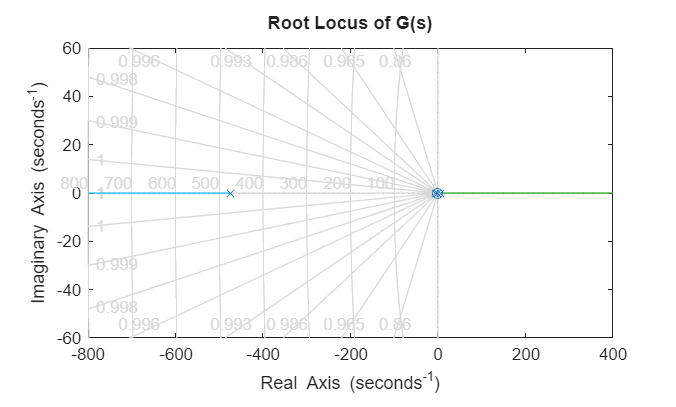


figure;
rlocus(G);
grid on;
title('Root Locus of G(s)');


syms Ki Kp Kd s
num_C=[Kd Kp Ki];
den_C=[1 0];
%C=tf(num,den);

syms s Kp Ki Kd
a2 = 475 - Kd*90.03;
a1 = -90.03*Kp - 62.02;
a0 = -15370 - Ki*90.03;
eqn = s^3 + a2*s^2 + a1*s + a0 == 0;

R = solve(eqn, s, 'MaxDegree', 3);
simplify(R)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{3001\,\mathrm{Kd}}{100}+\sigma_{1}+\frac{\sigma_{2}}{\sigma_{1}}-\frac{475}{3}\\ \frac{3001\,\mathrm{Kd}}{100}-\frac{\sigma_{1}}{2}-\frac{\sigma_{2}}{2\,\sigma_{1}}-\frac{475}{3}-\frac{\sqrt{3}\,\left(\sigma_{1}-\frac{\sigma_{2}}{\sigma_{1}}\right)\,\mathrm{i}}{2}\\ \frac{3001\,\mathrm{Kd}}{100}-\frac{\sigma_{1}}{2}-\frac{\sigma_{2}}{2\,\sigma_{1}}-\frac{475}{3}+\frac{\sqrt{3}\,\left(\sigma_{1}-\frac{\sigma_{2}}{\sigma_{1}}\right)\,\mathrm{i}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{9003\,\mathrm{Ki}}{200}+\frac{{\sigma_{4}}^{3}}{27}+\sigma_{3}+\sqrt{{\left(\frac{9003\,\mathrm{Ki}}{200}+\frac{{\sigma_{4}}^{3}}{27}+\sigma_{3}+7685\right)}^{2}-{\sigma_{2}}^{3}}+7685\right)}^{1/3}\\ \sigma_{2}=\frac{3001\,\mathrm{Kp}}{100}+\frac{{\sigma_{4}}^{2}}{9}+\frac{3101}{150}\\ \sigma_{3}=\frac{\sigma_{4}\,\left(\frac{9003\,\mathrm{Kp}}{100}+\frac{3101}{50}\right)}{6}\\ \sigma_{4}=\frac{9003\,\mathrm{Kd}}{100}-475 \end{array}$$

syms s Kp Ki Kd p1 p2 p3

% Given characteristic (from your reduction)
char_given = s^3 + (475 - Kd*90.03)*s^2 + (-90.03*Kp - 62.02)*s + (-15370 - Ki*90.03);

% Desired characteristic from chosen poles p1,p2,p3
char_des = expand((s - p1)*(s - p2)*(s - p3));

% Match coefficients: extract coefficient vectors [s^3 s^2 s^1 s^0]
coeffs_given = coeffs(char_given, s, 'All');
coeffs_des   = coeffs(char_des,   s, 'All');

% Solve for Kp, Ki, Kd
sol = solve(coeffs_given - coeffs_des == 0, [Kp, Ki, Kd], 'IgnoreAnalyticConstraints', true);

% Simplify solutions
Kp_sol = simplify(sol.Kp);
Ki_sol = simplify(sol.Ki);
Kd_sol = simplify(sol.Kd);

Kp_sol, Ki_sol, Kd_sol

$$Kp\_sol = -\frac{100\,p_{1}\,p_{2}}{9003}-\frac{100\,p_{1}\,p_{3}}{9003}-\frac{100\,p_{2}\,p_{3}}{9003}-\frac{6202}{9003}$$

$$Ki\_sol = \frac{100\,p_{1}\,p_{2}\,p_{3}}{9003}-\frac{1537000}{9003}$$

$$Kd\_sol = \frac{100\,p_{1}}{9003}+\frac{100\,p_{2}}{9003}+\frac{100\,p_{3}}{9003}+\frac{47500}{9003}$$

sys=zpk(G)


sys =
 
    -90.028 (s^2 + 4.575e-16)
  ------------------------------
  s (s+475.1) (s+5.657) (s-5.72)
 
Continuous-time zero/pole/gain model.


p1val=-475.1;
p2val=-5.657;
p3val=-3;
p4val=0;



Kp_num_sym = subs(Kp_sol, [p1 p2 p3], [p1val p2val p3val]);
Ki_num_sym = subs(Ki_sol, [p1 p2 p3], [p1val p2val p3val]);
Kd_num_sym = subs(Kd_sol, [p1 p2 p3], [p1val p2val p3val]);

Kp = double(Kp_num_sym)

Kp = -46.5615

Ki = double(Ki_num_sym)

Ki = -260.2790

Kd = double(Kd_num_sym)

Kd = -0.0973

3.6

alpha=I_w/l_w+m_w*l_w+l_w*m_b;
beta=I_b+m_b*l_b*l_b;

Gamma_m=[1 0 0 0;
        0 0 1 0;
        0 1 0 l_w*l_b*m_b/alpha;
        0 m_b*l_b/beta 0  1];
% Alpha_m=[0 0 1 0 ;
%         0 0 0 1;
%         0  0 -K_e*K_t/(R_m*l_w*alpha)+b_f/(l_w*alpha) K_e*K_t/(R_m*alpha)+b_f/alpha;
%         0  m_b*l_b*g/beta K_e*K_t/(R_m*l_w*beta)+b_f/(l_w*beta) -K_e*K_t/(R_m*beta)-b_f/beta];
Alpha_m=[0 1 0 0 ;
        0 0 0 1;
        0 -K_e*K_t/(R_m*l_w*alpha)+b_f/(l_w*alpha) 0 K_e*K_t/(R_m*alpha)+b_f/alpha;
        0 K_e*K_t/(R_m*l_w*beta)+b_f/(l_w*beta) m_b*l_b*g/beta -K_e*K_t/(R_m*beta)-b_f/beta];
Beta_m=[0 0;
        0 0;
        K_t/(R_m*alpha) l_w/alpha;
        -K_t/(R_m*beta) l_b/beta];


A=inv(Gamma_m)*Alpha_m

A = 1.0e+03 *

         0    0.0010         0         0
         0   -0.4350   -0.0061    0.0091
         0         0         0    0.0010
         0    1.9034    0.0620   -0.0400


B=inv(Gamma_m)*Beta_m

B =          0         0
   20.5759    2.1054
         0         0
  -90.0275    2.0256


C=eye(4)

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D=zeros(4,2)

D =      0     0
     0     0
     0     0
     0     0


3.8

fSamplingPeriod=1/25;

LabB

Control_M=ctrb(A,B)

Control_M = 1.0e+09 *

         0         0    0.0000    0.0000   -0.0000   -0.0000    0.0046    0.0004
    0.0000    0.0000   -0.0000   -0.0000    0.0046    0.0004   -2.2058   -0.2025
         0         0   -0.0000    0.0000    0.0000    0.0000   -0.0203   -0.0019
   -0.0000    0.0000    0.0000    0.0000   -0.0203   -0.0019    9.6527    0.8862


C=[0 0 1 0]

C =      0     0     1     0


Observ_M=obsv(A,C)

Observ_M = 1.0e+05 *

         0         0    0.0000         0
         0         0         0    0.0000
         0    0.0190    0.0006   -0.0004
         0   -9.0415   -0.1409    0.1905
